closestbin = @(freqs, fois) arrayfun(@(val) find(abs(freqs-val) == min(abs(freqs-val)), 1, 'last'), fois);
cmw = @(times, foi, fwhm) exp(2*1i*pi*foi*times).*exp(-4*log(2)*times.^2/fwhm.^2);

## Create synthetic data

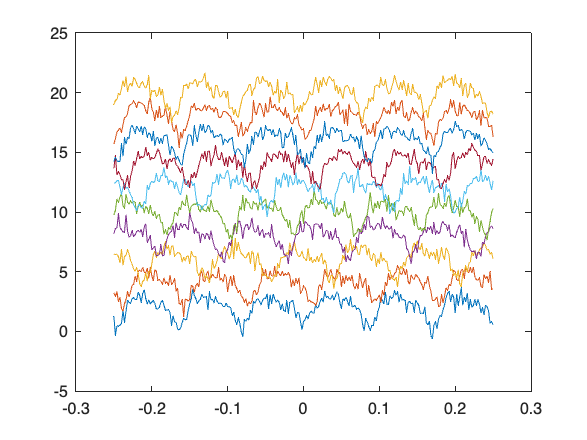

synthetic_fs = 500;
synthetic_t = -0.25:(1/synthetic_fs):0.25;

synthetic_numtrials = 100;

synthetic_foi = 12;
synthetic_harmonics_offsets = [0.75*pi -0.25*pi]';
synthetic_harmonics_amplitudes = [0.5 0.25]';

synthetic_noise_broadband = 5 * 1e-2;

synthetic_fftbin_cf = (0:numel(synthetic_t)) ./ diff(synthetic_t([1 end]));

assert(ismember(synthetic_foi, synthetic_fftbin_cf), 'frequency should match a bin center frequency exactly')

assert((size(synthetic_harmonics_offsets, 2) == 1) && all(size(synthetic_harmonics_offsets) == size(synthetic_harmonics_amplitudes)), ...
    'offset and amplitude dimensions must be column vectors of equal length')

synthetic_fftbin_harmonic_ixs = closestbin(synthetic_fftbin_cf, ((0:numel(synthetic_harmonics_offsets))+1) .* synthetic_foi);

synthetic_cplx = zeros(numel(synthetic_t), synthetic_numtrials);
synthetic_cplx(synthetic_fftbin_harmonic_ixs(1),:) = exp(1i * 2 * pi * rand(1, synthetic_numtrials));
synthetic_cplx(synthetic_fftbin_harmonic_ixs(2:end),:) = ...
    synthetic_cplx(synthetic_fftbin_harmonic_ixs(1),:) ...
    .* exp(1i * (1:numel(synthetic_harmonics_offsets))' .* angle(synthetic_cplx(synthetic_fftbin_harmonic_ixs(1),:))) ...
    .* exp(1i * synthetic_harmonics_offsets) ...
    .* synthetic_harmonics_amplitudes;
synthetic_cplx(2:end,:) = synthetic_cplx(2:end,:) + synthetic_noise_broadband * exp(1i * 2 * pi * rand(numel(synthetic_t)-1, synthetic_numtrials));
synthetic_trials = ifft(synthetic_cplx, 'symmetric') * (numel(synthetic_t)/2);

assert(all(isreal(synthetic_trials(:))))

figure, plot(synthetic_t, synthetic_trials(:,1:10) + 2*(1:10))

## PCA

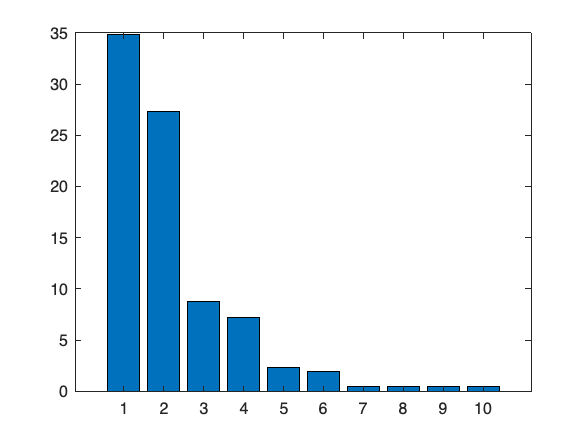

[coeff, score, ~, ~, explained] = pca(synthetic_trials);

bar(explained(1:10))

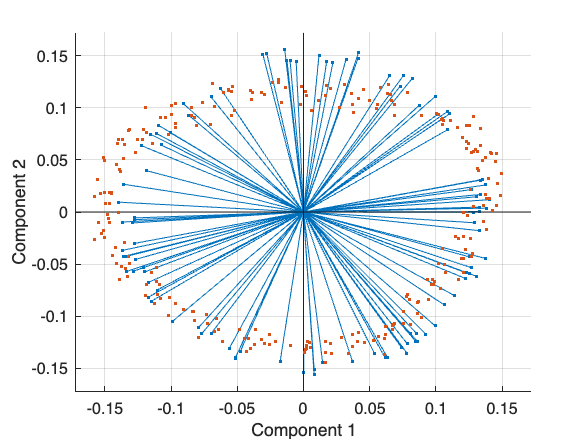

biplot(coeff(:,1:2),'scores',score(:,1:2));

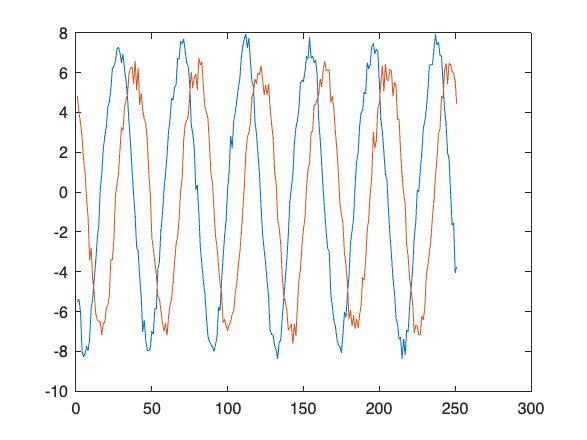


plot(score(:,1:2))

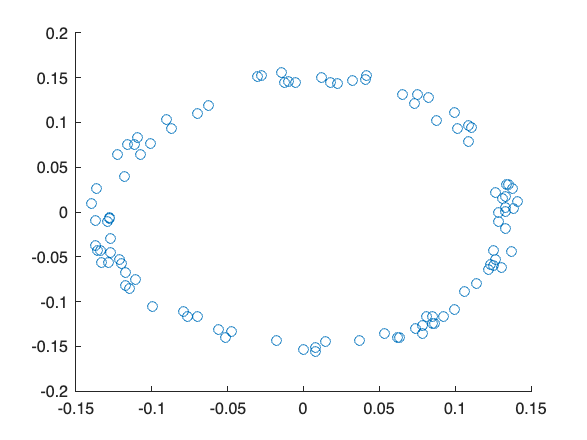

scatter(coeff(:,1), coeff(:,2))